# **4. Caracterización de regiones.**

En esta sección se discutirán los métodos y técnicas para describir una imagen y sus objetos o regiones de interés. Estás técnicas toman como consideración que las imágenes han sido segmetadas con anterioridad. La descripción de los objetos segmentados se representa mediante atributos y características.

La complejidad de la representación depende de varios factores:

- Tipo de imagen (tonalidad de grises, color, binario).

- Nivel de granularidad (toda al imagen o solo una región).

- Contexto de la aplicación.

La extracción de caracteristicas en un proceso por el cual ciertos atributos de interes dentro de la imagen son detectados para un posterior procesamiento. Es un paso fundamental ya que pasa de imagen o datos brutos a generar información. La representación final es útil se puede utilizar como entrada para técnicas de clasificación o de reconocimiento de patrones, con lo cual se etiqueta, clasifica y reconoce el contenido semantico de los contenidos en una imagen.

Como se menciono anteriormente un paso posterior a la segmentación es la extracción de caracteristicas, la cual consiste en la detección y descripción de características. 

- La detección se refiere a encontrar las características de una imagen, región y/o frontera. 

- La descripción de características asigna cuantitativamente atributos a las características encontradas. 

Por ejemplo, se pueden detectar esquinas de una frontera y describir esas esquinas por su orientación, locación, las cuales son atributos cuantitativos. Los procesos para la extracción de características se pueden dividir en tres grandes categorías, dependiendo su aplicabilidad a regiones, fronteras o la imagen completa. Los descriptores de características deben ser insensibles a la variación de parámetros como la escala, translacion, rotacion, iluminación y punto de vista.

## Vector de características e invarianza.

Un vector de características es una matriz *n × 1* que codifica las *n* características (o atributos) de una imagen u objeto. El contenido de la matriz puede ser simbólico (por ejemplo, una cadena que contiene el nombre del color predominante en la imagen), numérico (por ejemplo, un número entero que expresa el área de un objeto, en píxeles) o ambos. En la parte restante de nuestra discusión, nos centraremos exclusivamente en los vectores de características numéricas.

Matemáticamente, un vector de características numéricas *x* viene dado por

     
$$\mathbf{x}=\left(x_1 \;,x_1 ,\;\ldotp \ldotp \ldotp \;,x_n {\left.\right)}^{T\;} ;\;\;\;\;\;\;\;\;\;\;\;\;x_{i\;} \;\epsilon \;\Re \right.$$


donde *n* es el número total de características y *T* indica la operación de transposición.

El vector de características es una representación compacta de una imagen (u objeto dentro de la imagen), que puede asociarse con la noción de un espacio de características, un hiperespacio n-dimensional que permite la visualización (para n < 4) y la interpretación de la característica el contenido de los vectores, sus distancias relativas, y demás.

En Matlab se puede utilizar como carácteristicas de un objeto, las propiedades obtenidas con la funcion `regionprops( ).`

Un requisito común para las técnicas de extracción y representación de características sean invariables a la rotación, la escala y la translación, conocidas colectivamente como RST. La invariancia RST asegura que un sistema de visión artificial seguirá siendo capaz de reconocer objetos incluso cuando aparezcan en diferentes tamaños, posiciones dentro de la imagen y ángulos (en relación con una referencia horizontal). Claramente, este requisito depende de la aplicación. Por ejemplo, si el objetivo de un sistema de visión artificial es garantizar que un circuito integrado (IC) esté presente en la posición y orientación correctas en una placa de circuito impreso, la invariancia de rotación ya no es un requisito; por el contrario, saber que el CI está al revés es una parte integral del la funcionalidad del sistema.

Idealmente, la etapa de extracción y representación de características de un sistema de visión artificial debería proporcionar una representación que no solo sea invariante en RST, sino que también sea robusta a otros aspectos, como una resolución espacial deficiente, iluminación no uniforme, distorsiones geométricas (causadas por diferentes ángulos de visión) y ruido. Este es un gran desafío para los diseñadores de sistemas de visión artificial, que pueden requerir una selección cuidadosa de funciones, así como técnicas de pre y posprocesamiento para lograrlo por completo.

## Momentos estadísticos y momentos invariantes de Hu.

### Momentos espaciales.

Para un función 2D continua $f\left(x,y\right)$ el momento de orden $p+q$ está definido por   

                       

para p,q = 0,1,2,... 

El dominio de una imagen es discreto, y está dado por las coordenadas de sus píxeles.Tales coordenadas se expresan con números enteros. Por ello para una imagen la interpretando la función $f\left(x,y\right)$ como las intensidades de los  píxeles $I\left(x,y\right)$, los momentos de una imagen se calculan de la siguiente manera: 


$$\begin{array}{l}
M_{i\;j} =\sum_{x=X_1 }^{X_2 } \sum_{y=Y_1 }^{Y_2 } \left(x^i {\;y}^j \;I\left(x,y\right)\right)=\sum_{x=X_1 }^{X_2 } \sum_{y=Y_1 }^{Y_2 } g\left(x,y\right)\\
\textrm{suma}\;x=\left\lbrace X_1 \ldotp \ldotp \ldotp X_2 \right\rbrace \\
\;\;\;\;\;\;\textrm{suma}\;y=\left\lbrace Y_1 \ldotp \ldotp \ldotp Y_2 \right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;M_{\textrm{ij}} =M_{\textrm{ij}\;} +g\left(x,y\right)\;\;\;\;\;
\end{array}$$
        

Generalmente $I\left(x,y\right)$*, *se define para imagenes binarias, por tanto  $I\left(x,y\right)\;\epsilon \;\;\left\lbrace 0,1\right\rbrace$

El momento $M_{00\;}$ corresponde al área de la región, es decir, la cantidad de pixeles que contiene la región

$M_{00} =\sum_x \sum_y x^0 {\;y}^0 \;I\left(x,y\right)=\sum_x \sum_y \;I\left(x,y\right)$= Area

El momento $M_{10\;}$ y $M_{01\;}$se utilizan para obtener los centroides de las regiones

$M_{10} =\sum_x \sum_y x\;I\left(x,y\right)$;            $M_{01} =\sum_x \sum_y y\;I\left(x,y\right);$

$\bar{x} =\frac{M_{10} }{M_{00} }$;                                $\bar{y\;} =\frac{M_{01} }{M_{00} };$

### Momentos centrales: Invariantes a la translación.

Los momentos anteriores no son invariantes a la translación, por tanto, se utilizan los momentos centrales, estos dependen del centroide de la región u objeto de interes


$${\mu \;}_{i\;j} =\sum_x \sum_y {\left(x-\bar{x\;} \right)}^i {\;\left(y-\bar{y\;} \right)}^j \;I\left(x,y\right)$$
   

Momentos centrales de ejemplo hasta orden 3 son los siguientes

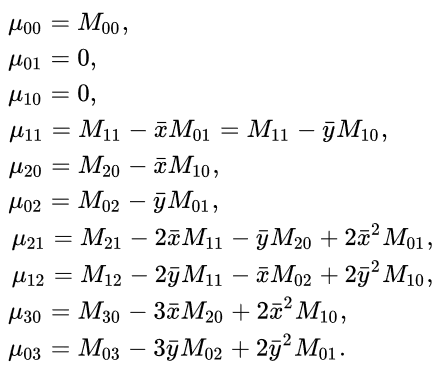

Aplicaciones específicas de estos momentos surgen de la matriz de covarianza 


$$\mu {\;}_{20} =$$

$$\sum_x \sum_y {\left(x-\bar{x\;} \right)}^2 \;I\left(x,y\right);$$
                
$$\mu {\;}_{02} =\sum_x \sum_y {\;\left(y-\bar{y\;} \right)}^2 \;I\left(x,y\right);$$
        
$$\;\;\;\mu {\;}_{1\;1} =\;\sum_x \sum_y {\left(x-\bar{x\;} \right)}^1 {\;\left(y-\bar{y\;} \right)}^1 \;I\left(x,y\right)$$


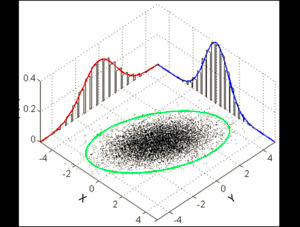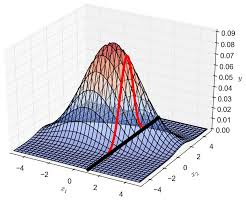

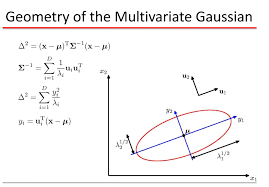

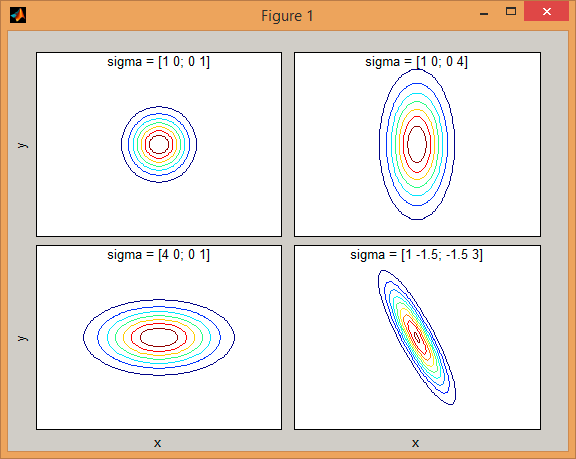

Donde los valores normalizados de los momentos centrales, se definen como:

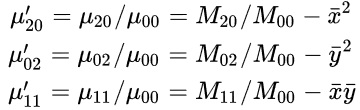

Dentro de la aplicaciones de la matriz de covariancia se encuentran la orientación del la región y la excentrecidad de la misma

### Orientación

Los autovalores de esta matriz corresponden a los ejes mayor y menor de la figura de la imagen. 

El autovalor mayor indica la orientación, el ángulo del eje mayor respecto del eje cartesiano más cercano (eje x o eje y) se puede calcular directamente a  partir de los momentos centrales: 

 

El ángulo se expresa entre -45º y 45º. Es necesario el cómputo de autovectores, para determinar el eje cartesiano de referencia para ese ángulo. 

### **Excentricidad**

La excentricidad es un valor entre 0 y 1. Cuando la excentricidad es 0, la figura es una circunferencia; mientras que para una excenticidad 1, la región es un segmento de línea.

### Momentos normales: invariantes a la translación y a la escala

Para obtener momentos invariantes a translación y escala, se requiere dividir los momentos centra entre una potencia apropiada del area de la imagen

#### Momentos de Hu: invariantes a la translación, escala y rotación

Los invariantes de Hu son 7 momentos bien conocidos, invariantes a la rotación, escala y traslación, y se calculan a partir de los momentos normales.

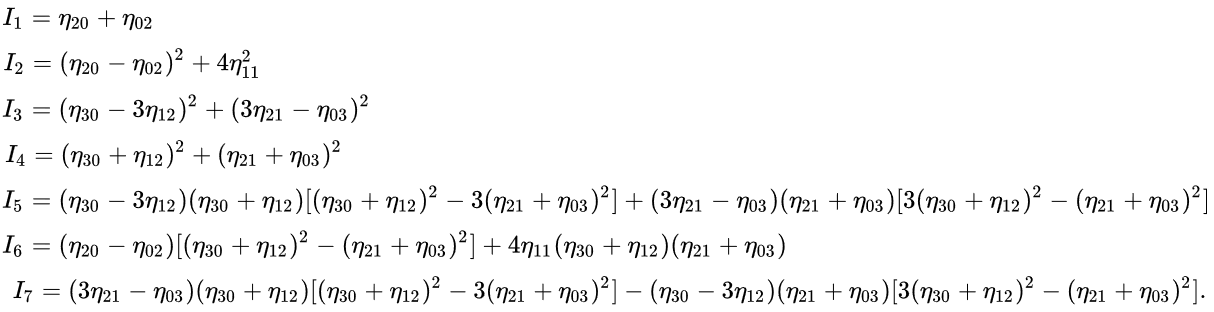

El primer invariante de Hu, $I_{1\;}$, es análogo al momento de inercia alrededor de centroide, donde las intensidades de los píxeles son análogas a densidad física. 

El último invariante de Hu, $I_{7\;}$, es invariante de torsión, el cual lo habilita para reconocer imágenes reflejadas. Dos valores de igual magnitud y diferente signo corresponden a imágenes reflejadas. 

Los invariantes de Hu se utilizan para reconocer formas 2D en diferentes posiciones (traslaciones), orientaciones (rotaciones) y tamaños  (escala). 

## Obtención de área -> centroide -> matriz de covarianza -> ejes de orientación -> Hu.

Actividad 4.1

Obtención de momentos espacial, centrales, normalizados


$$M_{i\;j} =\sum_x \sum_y x^i {\;y}^j \;I\left(x,y\right)$$


Entradas:

    Imagen segmentada *I*

    Region de interes [*x_min,y_min; x_max, y_max]*

    Orden del momento *i,j*

Salida

    Momento_ij

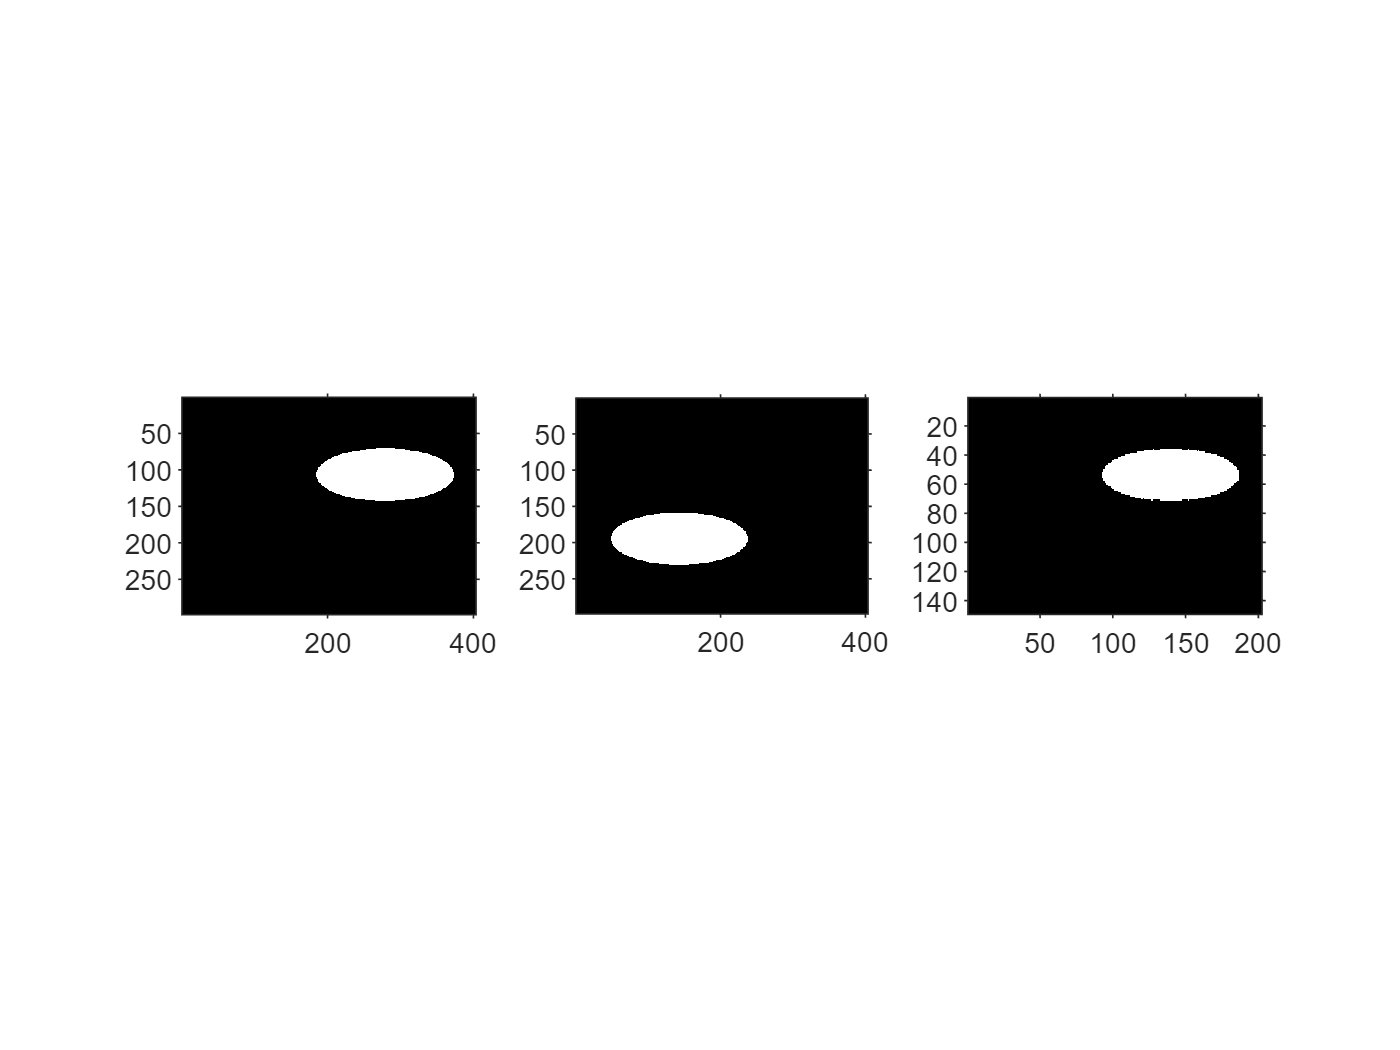

clc;
clear all;

I = imread('prueba.png');
% imshow(I);

BWO = imbinarize(rgb2gray(I));      %Imagen Original
I = imread('pruebaT.png');          
BWT = imbinarize(rgb2gray(I));          %Imagen Original Transladada
BWs = imresize(BWO, 0.50);             %Imagen Original Escalada
BWr = imrotate(BWs, 45, 'bilinear');    %Imagen Original Rotada
BWS = logical(zeros(size(BWO)));
% [M, N] = size(BWr);
% BWS(1:M, 1:N) = BWr; 



figure;
subplot(1,3,1);         imshow(BWO);        axis on;
subplot(1,3,2);         imshow(BWT);        axis on;
subplot(1,3,3);         imshow(BWs);        axis on;

region(:,:,1) = [1, 1; 403, 298];
region(:,:,2) = [1, 1; 403, 298];
region(:,:,3) = [1, 1; 403, 298];

BW{1} = BWO;
BW{2} = BWT;
BW{3} = BWS;
BW{4} = 'Texto'

BW = 1×4 cell array
    {298×403 logical}    {298×403 logical}    {298×403 logical}    {'Texto'}



% Para momentos de la imagen original
for i = 1:3
    Area(i) = MomentoEspacial(BW{i}, region(:,:,i), 0, 0);
    x_C(i) = MomentoEspacial(BW{i}, region(:,:,i), 1, 0)/Area(i);
    y_C(i) = MomentoEspacial(BW{i}, region(:,:,i), 0, 1)/Area(i);
    mu_02(i) = MomentoCentral(BW{i}, [x_C(i), y_C(i)], region(:,:,i), 0, 2);
    mu_11(i) = MomentoCentral(BW{i}, [x_C(i), y_C(i)], region(:,:,i), 1, 1);
    mu_20(i) = MomentoCentral(BW{i}, [x_C(i), y_C(i)], region(:,:,i), 2, 0);
    nu_02(i) = MomentoNormal(BW{i}, region(:,:,i), 0, 2);
    nu_11(i) = MomentoNormal(BW{i}, region(:,:,i), 1, 1);
    nu_20(i) = MomentoNormal(BW{i}, region(:,:,i), 2, 0);    
    nu_03(i) = MomentoNormal(BW{i}, region(:,:,i), 0, 3);    
    nu_21(i) = MomentoNormal(BW{i}, region(:,:,i), 2, 1);    
    nu_12(i) = MomentoNormal(BW{i}, region(:,:,i), 1, 2);    
    nu_30(i) = MomentoNormal(BW{i}, region(:,:,i), 3, 0);        
end

Nombres = {'Original', 'Translación', 'Escala'};
area = Area';
x = x_C';
y = y_C';
Tabla = table(Nombres', area, x, y, mu_02', mu_11', mu_20', nu_02', nu_11', nu_20', nu_30', nu_21', nu_12', nu_30')



## disp

for i = 1:3
    Hu(i,:) = MomentosHu(BW{i}, region(:,:,i));
    hu(i,:) = compute_phi(compute_eta(compute_m(BW{i})));
end
HuNorm = log10(abs(Hu))

HuNorm =    -0.6210   -1.4954   -8.5654   -9.2971  -18.3281  -10.3267  -18.4451
   -0.6210   -1.4954   -8.5654   -9.2971  -18.3281  -10.3267  -18.4451
   -0.6198   -1.4914   -8.2856   -9.4074  -18.2543  -10.1535  -19.6117


huNorm = log10(abs(hu))

huNorm =    -0.6210   -1.4954   -8.5654   -9.2971  -18.3281  -10.3267  -18.4451
   -0.6210   -1.4954   -8.5654   -9.2971  -18.3281  -10.3267  -18.4451
   -0.6198   -1.4914   -8.2856   -9.4074  -18.2543  -10.1535  -19.6117
